## Import

 
% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Time", "Time_s_", "IntensityCh1"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

[file, folder] = uigetfile('*.txt');
fullfile(folder, file)

ans = 'U:\Projekte an Analysis1\Christian\Misc\Hannah\230914\vCMC_Myh6-Piezo1-m_Tam+_stT_2mMCa_S01Z01L01-2.txt'

% Import the data
tbl = readtable(fullfile(folder, file), opts);

% Clear temporary variables
clear opts

% Display results
tbl

tbl = 65107×3 table
    Time     Time_s_     IntensityCh1
    ____    _________    ____________

      1             0       44.586   
      2     0.0009216       45.588   
      3     0.0018432       43.332   
      4     0.0027648       44.123   
      5     0.0036864       45.709   
      6      0.004608       46.361   
      7     0.0055296       45.961   
      8     0.0064512       46.098   
      9     0.0073728       46.109   
     10     0.0082944       47.268   
     11      0.009216       47.586   
     12      0.010138       45.107   
     13      0.011059       44.855   
     14      0.011981       45.287   
     15      0.012902       46.385   
     16      0.013824       46.625   


## Cleanup and Prep.

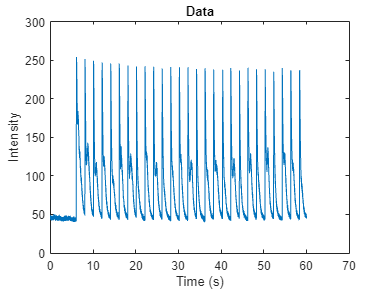

 
tbl=tbl(~any(ismissing(tbl),2),:);
tbl = tbl(:,2:3);
tbl.Properties.VariableNames = {'Time', 'Intensity'};
plot(tbl.Time, tbl.Intensity)
title("Data")
xlabel("Time (s)")
ylabel("Intensity")

## Smooth

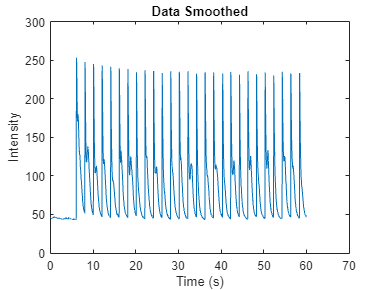

 
tbl = smoothdata(tbl,"movmedian",50,"DataVariables","Intensity");
plot(tbl.Time, tbl.Intensity)
title("Data Smoothed")
xlabel("Time (s)")
ylabel("Intensity")

Time = tbl.Time;
Intensity = tbl.Intensity;

## Find Peaks

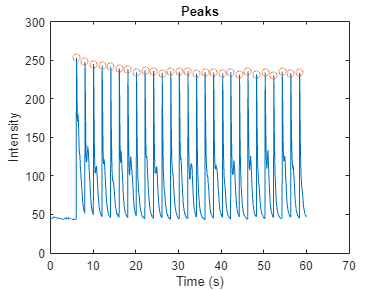

 
MinPeakProminence = 10;
MinPeakDistance = 1;
[pks,timePeak] = findpeaks(Intensity, Time ,'MinPeakProminence',MinPeakProminence,'MinPeakDistance', MinPeakDistance); %Prominence: https://de.mathworks.com/help/signal/ug/prominence.html
peakInterval = diff(timePeak);
plot(Time,Intensity, timePeak,pks,'o')
xlabel('Time (s)')
ylabel('Intensity')
title("Peaks")

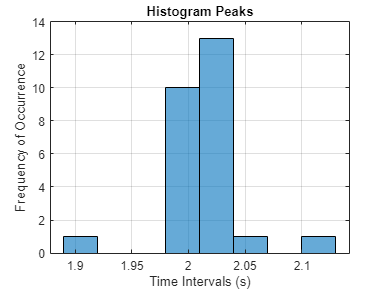

histogram(peakInterval)
title("Histogram Peaks")
grid on
xlabel('Time Intervals (s)')
ylabel('Frequency of Occurrence')

AverageDistance_Peaks = mean(diff(timePeak))

AverageDistance_Peaks = 2.0112

baselineDistance = -1.3;
for i = 1: numel(timePeak)
    [~, ix5] = min(abs(Time - (timePeak(i)-0.3)));
    [~, ix6] = min(abs(Time - (timePeak(i)+baselineDistance)));
    baseline(i) = median(Intensity(ix6:ix5));
end

## Fit

 
fitDistance = 1.9;
for i = 1: numel(timePeak)
    [~, ix1] = min(abs(Time - (timePeak(i)+0.1)));
    [~, ix2] = min(abs(Time - (timePeak(i)+fitDistance)));
    TimeFit = Time(ix1:ix2);
    IntensityFit = Intensity(ix1:ix2);
    [fitresult, gof] = createFit(TimeFit, IntensityFit);
    title(append("Fit: ", num2str(i)));
    axis padded
    tauFast = log(1/2) / fitresult.b;
    tauSlow = log(1/2) / fitresult.d;
    gof.tauSlow = tauSlow;
    gof.tauFast = tauFast;
    fitData(i) = struct('fit', fitresult, 'fitInfo', gof, 'Intensity', IntensityFit, 'Time', TimeFit);
end

## Taus

 
"T1/2 Slow"
for i = 1: numel(timePeak)
    slowTaus(i) = fitData(i).fitInfo.tauSlow;
    append(num2str(i),": ", num2str(slowTaus(i)))

end
"T1/2 Fast"

for i = 1: numel(timePeak)
    fastTaus(i) = fitData(i).fitInfo.tauFast;
    append(num2str(i),": ", num2str(fastTaus(i)))
end
append("Median Tau1/2 Slow: ", num2str(median(slowTaus)), " +- ", num2str(std(slowTaus)))
append("Median Tau1/2 Fast: ", num2str(median(fastTaus)), " +- ", num2str(std(fastTaus)))

figure;bar(slowTaus)
title("Tau1/2 Slow")
ylabel("Time in (s)")
figure;bar(fastTaus)
title("Tau1/2 Fast")
ylabel("Time in (s)")


## Time To

 
timeToVecStr ="25;50;75;90;100"; %Seperate Values by semicolon ;
splitStr = strsplit(timeToVecStr, ';');
timeToVec = arrayfun(@str2num,splitStr);
timeToTable = table('Size',[0,5],'VariableTypes', repelem("double",numel(splitStr)), 'Variablenames',append("Time to: ",splitStr, " (ms)"));
for i = 1: numel(timePeak)
    [~, ix3] = min(abs(Time - (timePeak(i)-1)));
    [~, ix4] = min(abs(Time - (timePeak(i)+1)));
    TimeTimeToCalc = Time(ix3:ix4);
    IntensityTimeToCalc = Intensity(ix3:ix4);
    try
        g = gradient(IntensityTimeToCalc, diff(TimeTimeToCalc(1:2)));
        ipt = findchangepts(g,'Statistic',"std");
        figure;
        plot(TimeTimeToCalc, IntensityTimeToCalc);
        title(append("Rising Edge: ", num2str(i)));
        xlabel("Time (s)")
        ylabel("Intensity")
        axis padded
        xline(TimeTimeToCalc(ipt), 'Color', 'red');
        yline(IntensityTimeToCalc(ipt), 'Color', 'red');
        yline(baseline(i), 'Color' , 'green');
        legend({'Intesity','Rising Edge','Rising Edge', 'Baseline'});
        IntensityTimeToCalc = 100 * normalize(IntensityTimeToCalc,  "range");
        IntensityTimeToCalc = IntensityTimeToCalc(ipt:find(timePeak(i) == TimeTimeToCalc));
        TimeTimeToCalc = TimeTimeToCalc(ipt:find(timePeak(i) == TimeTimeToCalc));
        [~,closestIndex] =  min(abs(IntensityTimeToCalc-timeToVec));
        timeToTable(i,:) = array2table((TimeTimeToCalc(closestIndex)-TimeTimeToCalc(1))');
    catch
        timeToTable(i,:) = table(NaN);
    end

end

timeToTable

for i = 1:numel(timeToVec)
    figure;bar(timeToTable{:,i}*1000)
    title(append("Time to: ", splitStr(i)))
    ylabel("Time in (ms)")
end

## Data

 
dataTable = table(fastTaus', slowTaus', pks, baseline', pks - baseline', pks ./ baseline', timePeak);
dataTable.Properties.VariableNames ={'FastTau1/2 (s)', 'SlowTau1/2 (s)', 'Peak Intensity', 'Baseline Intensity', 'Peak Intensity Abs','F/F0' ,'Peak Time (s)'};
dataTable = [dataTable timeToTable];
dataTable

## Save .Mat

 
uisave

## Save .csv

 
[folder, file] = uiputfile('*.csv')
writetable(dataTable, fullfile(file,folder))


## Save .html


 
[folder, file] = uiputfile('*.html')
export("AnalyseSparks.mlx",fullfile(file,folder),Format="html", OpenExportedFile=true, HideCode=true)